clear; clc; close all;

%% 1. Parametros nominales del motor
R  = 8;                 % Ohm
J  = 9.85e-3;           % kg*m^2
B  = 2.52e-3;           % Nm*s/rad
Km = 1.57e-2;           % Nm/A

%% 2. Parametros de la carga
M = 0.3;                % kg
r = 0.05;               % m
grav = 9.81;            % m/s^2

## Paso 2. Modelado del motor D.C.


$$
\[
u = Ri_a + L\frac{di_a}{dt} + V_b
\]

\[
\tau_m = J\ddot{\theta} + B\dot{\theta} + \tau_l
\]$$


Donde:

$u$ --> es el voltaje aplicado

$i_a$ --> la corriente de armadura

$R$ --> la resistencia

$L$ --> La inductancia

$J$ --> La inercia

$B$ --> La fricción viscosa

$\tau$ --> Torque de carga

Y como el taller asume que $L<<1$, se desprecia el termino inductivo


$$\[
L\frac{di_a}{dt} \approx 0
\]
$$


Por lo tanto 


$$\[
u = Ri_a + V_b
\]$$


Para un motor D.C. de iman permanente se tiene


$$
\[
V_b = K_m\dot{\theta}
\]

\[
\tau_m = K_m i_a
\]$$


como $x_1 =\theta \;$y $x_1 =\theta^{\bullet }$entonces 


$$

\[
u = Ri_a + K_m x_2
\]

Despejando la corriente:

\[
i_a = \frac{u-K_mx_2}{R}
\]

Luego, el torque del motor queda:

\[
\tau_m = K_m i_a
\]

\[
\tau_m = K_m\left(\frac{u-K_mx_2}{R}\right)
\]

\[
\tau_m = \frac{K_m}{R}u - \frac{K_m^2}{R}x_2
\]

Sustituyendo en la ecuación mecánica:

\[
J\dot{x}_2 + Bx_2 + \tau_l =
\frac{K_m}{R}u - \frac{K_m^2}{R}x_2
\]

Despejando \(\dot{x}_2\):

\[
J\dot{x}_2 =
\frac{K_m}{R}u
-
\left(B+\frac{K_m^2}{R}\right)x_2
-
\tau_l
\]

\[
\dot{x}_2 =
-\frac{B+\frac{K_m^2}{R}}{J}x_2
-\frac{\tau_l}{J}
+\frac{K_m}{RJ}u
\]$$


## Paso 3. Modelo de carga puntual

La carga puntual genera un torque gravitacional sobre el eje del motor. Como el ángulo cero corresponde a la barra en posición horizontal, se modela el torque de carga como:


$$
\[
\tau_l = Mgr\cos(x_1)
\]$$


donde $M$ es la masa, $g$ es la gravedad y $r$ es la distancia de la masa al eje. Sustituyendo este torque en el modelo obtenido:


$$
\[
\dot{x}_2 =
-\frac{B+\frac{K_m^2}{R}}{J}x_2
-\frac{Mgr}{J}\cos(x_1)
+\frac{K_m}{RJ}u
\]

Ahora se definen los coeficientes:

\[
\alpha = \frac{B+\frac{K_m^2}{R}}{J}
\]

\[
\gamma = \frac{Mgr}{J}
\]

\[
g_m = \frac{K_m}{RJ}
\]

Por lo tanto, el modelo en espacio de estados queda:

\[
\dot{x}_1 = x_2
\]

\[
\dot{x}_2 = -\alpha x_2 - \gamma \cos(x_1) + g_m u
\]

o equivalentemente,

\[
\dot{x}_2 = -f(x) + g_m u
\]

donde:

\[
f(x)=\alpha x_2+\gamma\cos(x_1)
\]

\[
g_m=\frac{K_m}{RJ}
\]$$


% Coeficientes del modelo:
% x2_dot = -f(x) + g*u
alpha = (B + Km^2/R)/J;
gamma = (M*grav*r)/J;
g_m     = Km/(R*J);

fprintf('alpha = %.4f\n', alpha);

alpha = 0.2590


fprintf('gamma = %.4f\n', gamma);

gamma = 14.9391


fprintf('g     = %.4f\n', g_m);

g     = 0.1992



%% Modelo obtenido:
% x1_dot = x2
% x2_dot = -alpha*x2 - gamma*cos(x1) + g_m*u



## Paso 4.  Definir la referencia de xr

El taller afirma que esta en un rango de [-30, 30], y dado que MATLAB trabaja en radianes se pasa a radianes 

xr_deg = 30;                 % Referencia en grados
xr = xr_deg*pi/180;          % Referencia en radianes

## Paso 5. Definir el parametro de la superficie de deslizamiento


$$
\[
s = a x_e + x_2
\]

Si \(s = 0\), entonces:

\[
a x_e + x_2 = 0
\]

Despejando \(x_2\):

\[
x_2 = -a x_e
\]

Como:

\[
\dot{x}_e = x_2
\]

entonces:

\[
\dot{x}_e = -a x_e
\]

Por eso, si \(a > 0\), el error \(x_e\) tiende a cero.
$$


a = 5;

## Paso 6. Calculo de beta usando la condición

La condición es:


$$

\[
\beta > \frac{\left|a x_2 - f(x)\right|}{|g|}
\]

Modelo:

\[
\dot{x}_2 = -f(x) + g_m u
\]

donde:

\[
f(x) = \alpha x_2 + \gamma \cos(x_1)
\]

Entonces:

\[
a x_2 - f(x)
= a x_2 - \alpha x_2 - \gamma \cos(x_1)
\]

\[
a x_2 - f(x)
= (a-\alpha)x_2 - \gamma \cos(x_1)
\]

Como el taller da:

\[
|x_2| \leq \frac{\pi}{2}
\]

y sabemos que:

\[
|\cos(x_1)| \leq 1
\]

entonces:

\[
\left|a x_2 - f(x)\right|
\leq
|a-\alpha|\frac{\pi}{2} + \gamma
\]

Por tanto, una condición suficiente es:

\[
\beta >
\frac{
|a-\alpha|\frac{\pi}{2} + \gamma
}{
|g_m|
}
\]
$$


x2_max = pi/2;

beta_min = (abs(a - alpha)*x2_max + gamma)/abs(g_m);


% Se escoge beta un poco mayor que beta_min
beta_f = 1.2*beta_min;

fprintf('\n--- Diseno de beta nominal ---\n');


--- Diseno de beta nominal ---


fprintf('a = %.6f\n', a);

a = 5.000000


fprintf('beta_min = %.6f\n', beta_min);

beta_min = 112.359192


fprintf('beta usada = %.6f\n', beta_f);

beta usada = 134.831030




%% Paso 6B. Calculo de beta para control equivalente

% Incertidumbre del 20%
R_max  = 1.2*R;
J_max  = 1.2*J;
B_min  = 0.8*B;
Km_min = 0.8*Km;

M_max = 1.2*M;
r_max = 1.2*r;

% Cota de velocidad dada por el taller
x2_max = pi/2;

% Beta para la parte conmutada del control equivalente
beta_eq = ((J_max*R_max/Km_min) - (J*R/Km)) * ...
          (a*x2_max + (Km^2/(J*R) + B/J)*x2_max) ...
          + (M_max*grav*r_max/J);

beta_eq = ceil(beta_eq);

fprintf('\n--- Diseno de beta para control equivalente ---\n');


--- Diseno de beta para control equivalente ---


fprintf('a = %.6f\n', a);

a = 5.000000


fprintf('beta_eq = %.6f\n', beta_eq);

beta_eq = 55.000000


## Paso 7. Condiciones iniciales

x1_0_deg = 0;             % Posicion inicial [grados]
x1_0 = x1_0_deg*pi/180;  % Posicion inicial [rad]

x2_0 = 0;                 % Velocidad inicial [rad/s]

x0 = [x1_0; x2_0];

## Paso 8. Graficas

%% 8. Graficas variando el parametro a

% IMPORTANTE:
% En Simulink agrega bloques "To Workspace" para guardar:
%
% x1   <- posicion x1
% x2   <- velocidad x2
% dx2  <- aceleracion dx2
% u    <- senal de control u
%
% En cada bloque To Workspace, coloca:
% Save format: Timeseries
%
% El modelo de Simulink debe usar las variables:
% a, beta_f, xr, alpha, gamma, g_m, x1_0, x2_0

% Si estas usando saturation en vez de sign:
phi = 0.01;     % el modelo usa saturation con s/phi

valores_a = [0.2 0.5 1 2 5];
valores_a = fliplr(valores_a);   % grafica primero a = 5

betas = zeros(1,length(valores_a));

% Colores personalizados
colores = [
    0.12 0.47 0.71;   % azul
    1.00 0.50 0.05;   % naranja
    0.17 0.63 0.17;   % verde
    0.84 0.15 0.16;   % rojo
    0.58 0.40 0.74    % morado
];

%% Crear figuras

fig_x1 = figure; hold on; grid on;
title('Respuesta en el Tiempo - SMC','Interpreter','latex');
xlabel('Tiempo [s]','Interpreter','latex');
ylabel('$\theta [^\circ]$','Interpreter','latex');

fig_x2 = figure; hold on; grid on;
title('Velocidad en el Tiempo - SMC','Interpreter','latex');
xlabel('Tiempo [s]','Interpreter','latex');
ylabel('$\dot{\theta} [^\circ/s]$','Interpreter','latex');

fig_dx2 = figure; hold on; grid on;
title('Aceleracion en el Tiempo - SMC','Interpreter','latex');
xlabel('Tiempo [s]','Interpreter','latex');
ylabel('$\ddot{\theta} [^\circ/s^2]$','Interpreter','latex');

fig_u = figure; hold on; grid on;
title('Senal de control vs. tiempo - SMC','Interpreter','latex');
xlabel('Tiempo [s]','Interpreter','latex');
ylabel('$u$','Interpreter','latex');

fig_des = figure; hold on; grid on;
title('Superficie de deslizamiento - SMC','Interpreter','latex');
xlabel('$x_1 [^\circ]$','Interpreter','latex');
ylabel('$x_2 [^\circ/s]$','Interpreter','latex');

%% Graficar referencia en la grafica de posicion

figure(fig_x1);
yline(xr_deg,'k--','DisplayName','ref','LineWidth',1.8);

%% Ciclo para simular varios valores de a

for i = 1:length(valores_a)

    % Cambiar parametro a
    a = valores_a(i);

    % Recalcular beta para este valor de a
    beta_min = (abs(a - alpha)*x2_max + gamma)/abs(g_m);

    % Escoger beta con margen
    beta_f = 1.2*beta_min;

    % Redondear hacia arriba
    beta_f = ceil(beta_f);

    % Guardar beta
    betas(i) = beta_f;

    fprintf('\nCaso %d:\n',i);
    fprintf('a = %.3f\n',a);
    fprintf('beta_min = %.3f\n',beta_min);
    fprintf('beta_f = %.3f\n',beta_f);

    % Ejecutar simulacion
    simOut = sim("Modelo_tarea2","ReturnWorkspaceOutputs","on");

    % Extraer datos desde To Workspace
    x1_ts  = simOut.x1;
    x2_ts  = simOut.x2;
    dx2_ts = simOut.dx2;
    u_ts   = simOut.u;

    % Extraer tiempo y datos
    t   = x1_ts.Time;
    x1  = x1_ts.Data;
    x2  = x2_ts.Data;
    dx2 = dx2_ts.Data;
    u   = u_ts.Data;

    % Asegurar que las senales sean vectores columna
    x1  = x1(:);
    x2  = x2(:);
    dx2 = dx2(:);
    u   = u(:);
    t   = t(:);

    % Convertir a grados
    x1_deg  = x1*180/pi;
    x2_deg  = x2*180/pi;
    dx2_deg = dx2*180/pi;

    % Color del caso actual
    c = colores(i,:);

    % Graficar posicion
    figure(fig_x1);
    plot(t,x1_deg,'LineWidth',1.5,'Color',c, ...
        'DisplayName',['a = ' num2str(a)]);

    % Graficar velocidad
    figure(fig_x2);
    plot(t,x2_deg,'LineWidth',1.5,'Color',c, ...
        'DisplayName',['a = ' num2str(a)]);

    % Graficar aceleracion
    figure(fig_dx2);
    plot(t,dx2_deg,'LineWidth',1.5,'Color',c, ...
        'DisplayName',['a = ' num2str(a)]);

    % Graficar senal de control
    figure(fig_u);
    plot(t,u,'LineWidth',1.5,'Color',c, ...
        'DisplayName',['a = ' num2str(a)]);

    % Graficar superficie de deslizamiento en plano fase
    figure(fig_des);
    plot(x1_deg,x2_deg,'LineWidth',1.5,'Color',c, ...
        'DisplayName',['a = ' num2str(a)]);

end


Caso 1:


a = 5.000


beta_min = 112.359


beta_f = 135.000



Caso 2:


a = 2.000


beta_min = 88.707


beta_f = 107.000



Caso 3:


a = 1.000


beta_min = 80.823


beta_f = 97.000



Caso 4:


a = 0.500


beta_min = 76.881


beta_f = 93.000



Caso 5:


a = 0.200


beta_min = 75.446


beta_f = 91.000


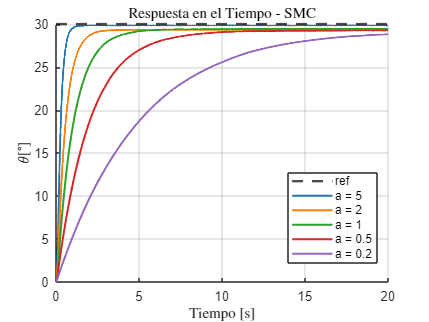


%% Mostrar leyendas

figure(fig_x1); legend show; legend('Location','best');
figure(fig_x2); legend show; legend('Location','best');
figure(fig_dx2); legend show; legend('Location','best');
figure(fig_u); legend show; legend('Location','best');
figure(fig_des); legend show; legend('Location','best');

%% Guardar imagenes

saveas(fig_x1,'SMC_x1.png');

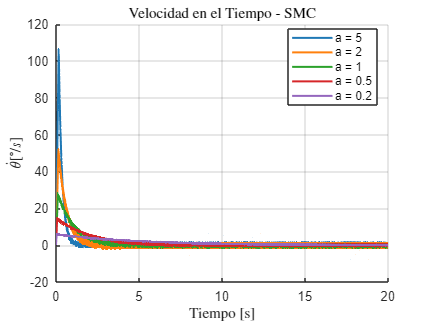

saveas(fig_x2,'SMC_x2.png');

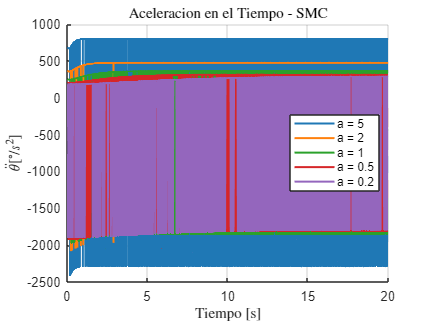

saveas(fig_dx2,'SMC_dx2.png');

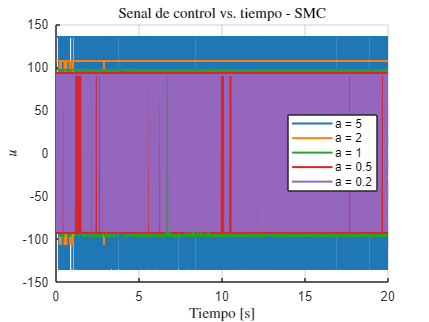

saveas(fig_u,'SMC_u.png');

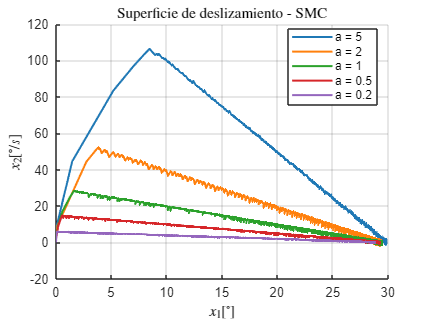

saveas(fig_des,'Deslizamiento_SMC.png');


%% Mostrar betas usadas

disp('Betas usadas para cada valor de a:');

Betas usadas para cada valor de a:


disp(table(valores_a',betas','VariableNames',{'a','beta_f'}));

     a     beta_f
    ___    ______

      5     135  
      2     107  
      1      97  
    0.5      93  
    0.2      91  



dfddfdd

%% 8. Graficas variando el parametro a - SMC con control equivalente

% IMPORTANTE:
% En Simulink agrega bloques "To Workspace" para guardar:
%
% x1   <- posicion x1
% x2   <- velocidad x2
% dx2  <- aceleracion dx2
% u    <- senal de control total u = ueq + usm
%
% En cada bloque To Workspace, coloca:
% Save format: Timeseries
%
% El modelo de Simulink debe usar las variables:
% a, beta_eq, phi, xr, alpha, gamma, g_m, x1_0, x2_0
%
% El controlador en Simulink debe ser:
%
% ueq = ((alpha - a)*x2 + gamma*cos(x1))/g_m
% usm = -beta_eq*sat(s/phi)
% u   = ueq + usm
%
% donde:
% s = a*(x1 - xr) + x2

%% Nombre del modelo equivalente

modelo_eq = "Modelo_EQU_tarea2";   
% Cambia este nombre si tu modelo se llama diferente.
% Por ejemplo:
% modelo_eq = "Modelo_tarea2";

%% Parametros de saturacion

phi = 0.01;     % capa limite para sat(s/phi)

%% Valores de a

valores_a = [0.2 0.5 1 2 5];
valores_a = fliplr(valores_a);   % grafica primero a = 5

betas_eq = zeros(1,length(valores_a));

%% Cotas para calcular beta_eq

x1_max = pi;
x2_max = pi/2;

% Incertidumbre del 20%
R_min  = 0.8*R;
R_max  = 1.2*R;

J_min  = 0.8*J;
J_max  = 1.2*J;

B_min  = 0.8*B;
B_max  = 1.2*B;

Km_min = 0.8*Km;
Km_max = 1.2*Km;

M_min = 0.8*M;
M_max = 1.2*M;

r_min = 0.8*r;
r_max = 1.2*r;

% Numero de muestras para buscar una beta conservadora
N_beta = 5000;
rng(1);

%% Colores personalizados

colores = [
    0.12 0.47 0.71;   % azul
    1.00 0.50 0.05;   % naranja
    0.17 0.63 0.17;   % verde
    0.84 0.15 0.16;   % rojo
    0.58 0.40 0.74    % morado
];

%% Crear figuras

fig_x1 = figure; hold on; grid on;
title('Respuesta en el Tiempo - SMC Equivalente','Interpreter','latex');
xlabel('Tiempo [s]','Interpreter','latex');
ylabel('$\theta [^\circ]$','Interpreter','latex');

fig_x2 = figure; hold on; grid on;
title('Velocidad en el Tiempo - SMC Equivalente','Interpreter','latex');
xlabel('Tiempo [s]','Interpreter','latex');
ylabel('$\dot{\theta} [^\circ/s]$','Interpreter','latex');

fig_dx2 = figure; hold on; grid on;
title('Aceleracion en el Tiempo - SMC Equivalente','Interpreter','latex');
xlabel('Tiempo [s]','Interpreter','latex');
ylabel('$\ddot{\theta} [^\circ/s^2]$','Interpreter','latex');

fig_u = figure; hold on; grid on;
title('Senal de control vs. tiempo - SMC Equivalente','Interpreter','latex');
xlabel('Tiempo [s]','Interpreter','latex');
ylabel('$u = u_{eq}+u_{sm}$','Interpreter','latex');

fig_des = figure; hold on; grid on;
title('Superficie de deslizamiento - SMC Equivalente','Interpreter','latex');
xlabel('$x_1 [^\circ]$','Interpreter','latex');
ylabel('$x_2 [^\circ/s]$','Interpreter','latex');

%% Graficar referencia

figure(fig_x1);
yline(xr_deg,'k--','DisplayName','ref','LineWidth',1.8);

%% Ciclo para simular varios valores de a

for i = 1:length(valores_a)

    % Cambiar parametro a
    a = valores_a(i);

    %% Calculo de beta_eq usando la condicion del Paso II
    %
    % beta_eq debe cumplir:
    %
    % beta_eq > |delta(x)| / |g(x)|
    %
    % donde:
    %
    % delta(x) = a*(1 - g/g_hat)*x2 + h(x) - (g/g_hat)*h_hat(x)
    %
    % Se busca una cota numerica considerando variacion del 20%.

    rho_max = 0;

    for k = 1:N_beta

        % Parametros reales aleatorios dentro de +-20%
        Rr  = R_min  + (R_max  - R_min)*rand;
        Jr  = J_min  + (J_max  - J_min)*rand;
        Br  = B_min  + (B_max  - B_min)*rand;
        Kmr = Km_min + (Km_max - Km_min)*rand;

        Mr = M_min + (M_max - M_min)*rand;
        rr = r_min + (r_max - r_min)*rand;

        % Estados dentro de las cotas del taller
        x1_rand = -x1_max + 2*x1_max*rand;
        x2_rand = -x2_max + 2*x2_max*rand;

        % Modelo real
        alpha_r = (Br + Kmr^2/Rr)/Jr;
        gamma_r = (Mr*grav*rr)/Jr;
        g_r = Kmr/(Rr*Jr);

        h_r = -alpha_r*x2_rand - gamma_r*cos(x1_rand);

        % Modelo nominal
        h_hat = -alpha*x2_rand - gamma*cos(x1_rand);
        g_hat = g_m;

        % Incertidumbre equivalente
        delta = a*(1 - g_r/g_hat)*x2_rand + h_r - (g_r/g_hat)*h_hat;

        % Cota requerida para beta
        rho = abs(delta)/abs(g_r);

        if rho > rho_max
            rho_max = rho;
        end
    end

    % Escoger beta_eq con margen
    beta_eq = 1.2*rho_max;

    % Redondear hacia arriba
    beta_eq = ceil(beta_eq);

    % Guardar beta
    betas_eq(i) = beta_eq;

    fprintf('\nCaso equivalente %d:\n',i);
    fprintf('a = %.3f\n',a);
    fprintf('rho_max = %.3f\n',rho_max);
    fprintf('beta_eq = %.3f\n',beta_eq);

    %% Ejecutar simulacion

    simOut = sim(modelo_eq,"ReturnWorkspaceOutputs","on");

    %% Extraer datos desde To Workspace

    x1_ts  = simOut.x1;
    x2_ts  = simOut.x2;
    dx2_ts = simOut.dx2;
    u_ts   = simOut.u;

    %% Extraer tiempo y datos

    t   = x1_ts.Time;
    x1  = x1_ts.Data;
    x2  = x2_ts.Data;
    dx2 = dx2_ts.Data;
    u   = u_ts.Data;

    % Asegurar que las senales sean vectores columna
    t   = t(:);
    x1  = x1(:);
    x2  = x2(:);
    dx2 = dx2(:);
    u   = u(:);

    %% Convertir a grados

    x1_deg  = x1*180/pi;
    x2_deg  = x2*180/pi;
    dx2_deg = dx2*180/pi;

    %% Color del caso actual

    c = colores(i,:);

    %% Graficar posicion

    figure(fig_x1);
    plot(t,x1_deg,'LineWidth',1.5,'Color',c, ...
        'DisplayName',['a = ' num2str(a)]);

    %% Graficar velocidad

    figure(fig_x2);
    plot(t,x2_deg,'LineWidth',1.5,'Color',c, ...
        'DisplayName',['a = ' num2str(a)]);

    %% Graficar aceleracion

    figure(fig_dx2);
    plot(t,dx2_deg,'LineWidth',1.5,'Color',c, ...
        'DisplayName',['a = ' num2str(a)]);

    %% Graficar senal de control total

    figure(fig_u);
    plot(t,u,'LineWidth',1.5,'Color',c, ...
        'DisplayName',['a = ' num2str(a)]);

    %% Graficar superficie de deslizamiento en plano fase

    figure(fig_des);
    plot(x1_deg,x2_deg,'LineWidth',1.5,'Color',c, ...
        'DisplayName',['a = ' num2str(a)]);

end


Caso equivalente 1:


a = 5.000


rho_max = 71.580


beta_eq = 86.000



Caso equivalente 2:


a = 2.000


rho_max = 68.691


beta_eq = 83.000



Caso equivalente 3:


a = 1.000


rho_max = 69.847


beta_eq = 84.000



Caso equivalente 4:


a = 0.500


rho_max = 68.556


beta_eq = 83.000



Caso equivalente 5:


a = 0.200


rho_max = 58.151


beta_eq = 70.000


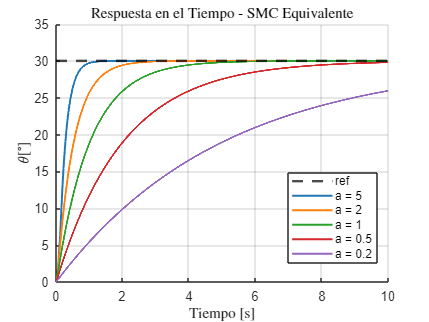


%% Mostrar leyendas

figure(fig_x1); legend('show','Location','best');
figure(fig_x2); legend('show','Location','best');
figure(fig_dx2); legend('show','Location','best');
figure(fig_u); legend('show','Location','best');
figure(fig_des); legend('show','Location','best');

%% Guardar imagenes

saveas(fig_x1,'EqSMC_x1.png');

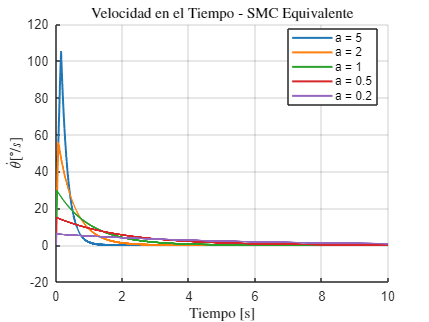

saveas(fig_x2,'EqSMC_x2.png');

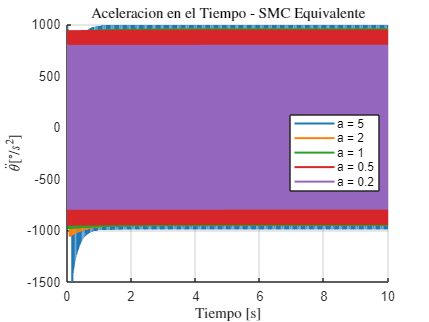

saveas(fig_dx2,'EqSMC_dx2.png');

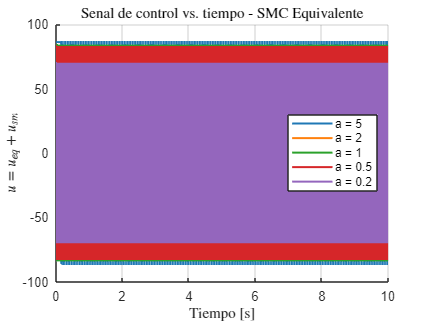

saveas(fig_u,'EqSMC_u.png');

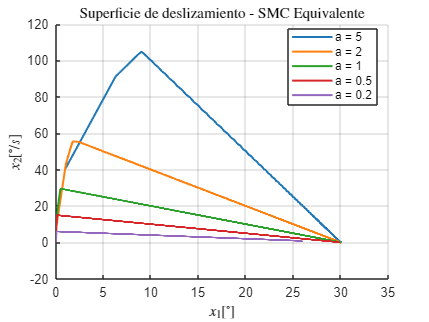

saveas(fig_des,'Deslizamiento_EqSMC.png');


%% Mostrar betas usadas

disp('Betas usadas para cada valor de a en SMC equivalente:');

Betas usadas para cada valor de a en SMC equivalente:


disp(table(valores_a',betas_eq','VariableNames',{'a','beta_eq'}));

     a     beta_eq
    ___    _______

      5      86   
      2      83   
      1      84   
    0.5      83   
    0.2      70   

